# Lab 2 - Passive Membrane Properties

## 1). Passive Membrane Properties as RC Circuits

Open the Matlab m-file “rc.m”. In this simulation, we will investigate how the membrane potential responds to a steady current input. Here, the membrane potential is modeled using the parallel RC equivalent circuit model.

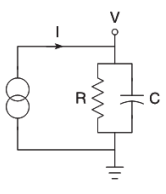

### a). Default Output

Run the model with the default parameters (R = 10 MΩ, C = 1 µF, I = 1 nA) and describe the output. What is the steady state voltage? Approximately how long does it take the membrane potential to reach steady state (>99% of the steady state voltage)? *Note: For all questions, adjust the x and y axes on your plots appropriately before pasting them into your lab notebook.

% Run simulation
[time, Istep, V] = rc('R', 10, 'C', 1, 'I', 1);

% Compute steady state metrics
[t_SS, V_SS] = find_SS(time, V, 1, 10);
print_rc(V_SS, t_SS)

The steady state voltage, V_SS = 10.00 mV.
It took 46.05 seconds from current injection for the voltage to reach steady state.

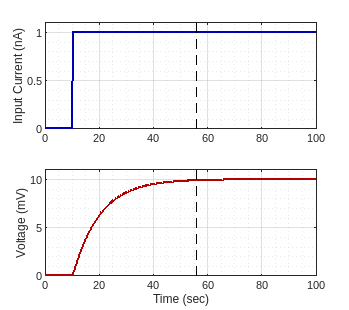

% Plot results
plot_rc(time, Istep, V, t_SS)

- With default parameters, it takes 46.05 seconds from the current injection for the membrane potential to reach a steady state value of 10mV.

### b). Parameter Effects

Resetting to the default values each time (R = 10 MΩ, C = 1 µF, I = 1 nA), determine what effects the following parameters have on the resulting membrane potential time course and steady state values (make sure to describe the effects): 

% Default parameters
p = struct('R', 10, 'C', 1, 'I', 1);
volts = zeros(2, numel(time));

#### i). Multiplying R by 5

% Run simulations
labs = {'Default params', '5x Resistance'};
[time, Istep, volts(1, :)] = rc('R', p.R, 'C', p.C, 'I', p.I);
[~, ~, volts(2, :)] = rc('R', p.R * 5, 'C', p.C, 'I', p.I);  % R * 5

% Compute steady state metrics
[t_SS, V_SS] = find_SS(time, volts, [p.I p.I], [p.R p.R*5]);
print_rc(V_SS, t_SS, labs)

Default params:
The steady state voltage, V_SS = 10.00 mV.
It took 46.05 seconds from current injection for the voltage to reach steady state.

5x Resistance:
The steady state voltage, V_SS = 50.00 mV.
It took 230.25 seconds from current injection for the voltage to reach steady state.



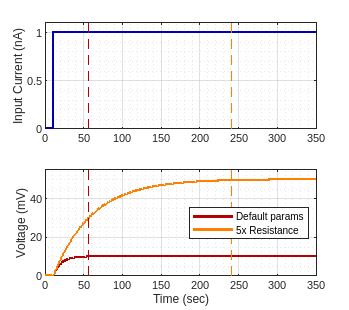

% Plot results
plot_rc(time, Istep, volts, t_SS, labs)
xlim([0 350])

- When the resistance is increased by a factor of 5, we see a corresponding increase in the steady state voltage to 50mV.

- It also takes 5 times longer for the membrane voltage to reach steady state (230.25 seconds).

#### ii). Dividing C by 10

% Run simulations
labs = {'Default params', 'Capacitance / 10'};
[time, Istep, volts(1, :)] = rc('R', p.R, 'C', p.C, 'I', p.I);
[~, ~, volts(2, :)] = rc('R', p.R, 'C', p.C / 10, 'I', p.I);  % C / 10

% Compute steady state metrics
[t_SS, V_SS] = find_SS(time, volts, [p.I p.I], [p.R p.R]);
print_rc(V_SS, t_SS, labs)

Default params:
The steady state voltage, V_SS = 10.00 mV.
It took 46.05 seconds from current injection for the voltage to reach steady state.

Capacitance / 10:
The steady state voltage, V_SS = 10.00 mV.
It took 4.60 seconds from current injection for the voltage to reach steady state.



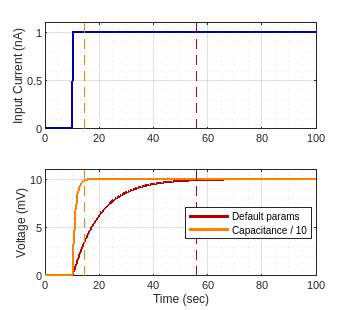

% Plot results
plot_rc(time, Istep, volts, t_SS, labs)

- Decreasing the membrane capacitance does not impact the steady state membrane voltage.

- However, it does decrease the time it takes to reach steady state to only 4.6 seconds from current injection.

#### iii). Multiplying R by 10 and dividing C by 10

% Run simulations
labs = {'Default params', '10xR, C/10'};
[time, Istep, volts(1, :)] = rc('R', p.R, 'C', p.C, 'I', p.I);
[~, ~, volts(2, :)] = rc('R', p.R * 10, 'C', p.C / 10, 'I', p.I);  % R * 10, C / 10

% Compute steady state metrics
[t_SS, V_SS] = find_SS(time, volts, [p.I p.I], [p.R p.R * 10]);
print_rc(V_SS, t_SS, labs)

Default params:
The steady state voltage, V_SS = 10.00 mV.
It took 46.05 seconds from current injection for the voltage to reach steady state.

10xR, C/10:
The steady state voltage, V_SS = 100.00 mV.
It took 46.05 seconds from current injection for the voltage to reach steady state.



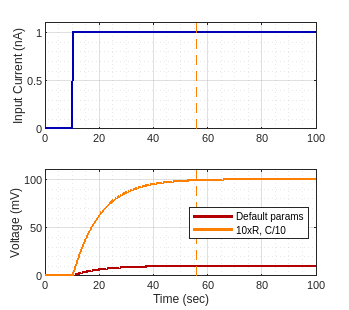

% Plot results
plot_rc(time, Istep, volts, t_SS, labs)

- We see a 10 fold increase in the steady state voltage (Vss = 100mV) when membrane resistance is increased and capacitance is decreased.

- The time taken to reach steady state remains constant (46.05 seconds).

### c). Measuring Time Constant

A way in which the time constant τ can be obtained when either R or C or both are uncertain is to measure the time after constant current onset where the membrane potential reaches approximately 63.2% of its steady state value (Hint: 0.632*Vss= 0.632*Istim*R). Test this by varying the input current, the resistance and the capacitance and compare the measured values of τ (remember the stimulus is turned on at t = 10 sec!) to the theoretical values obtained from τ = R*C. Provide a table with the column headers below to display your input parameters and results for at least 6 trials. Provide a theoretical justification for why this method works. 

% Given trials
Istims = [1 1 1 2 1 2];
Rs = [10 20 10 10 5 20];
Cs = [1 1 0.5 1 2 0.5];

% Results
results = zeros(length(Istims), 7);

for i = 1:length(Istims)
    [time, ~, V] = rc('R', Rs(i), 'C', Cs(i), 'I', Istims(i));
    
    % Theoretical values
    tau = Rs(i) * Cs(i);
    [~, V_SS] = find_SS(time, V, Istims(i), Rs(i));
    V_632 = 0.632 * V_SS;
    
    % Finding time at 0.632*Vss after stimulus onset
    stim_onset = 10;
    time_adj = time - stim_onset;  % Adjust time so that stimulus onset corresponds to t=0
    time_632 = time_adj(find((V >= V_632) & (time >= stim_onset), 1));
    
    % Log Results
    results(i, :) = [Istims(i), Rs(i), Cs(i), tau, V_SS, V_632, time_632];
end

% Display table
T = array2table(results, 'VariableNames', {'Istim', 'R', 'C', 'tau', 'Vss', '0.632_Vss', 'Time_at_0.632Vss'});
disp(T);

    Istim    R      C     tau    Vss    0.632_Vss    Time_at_0.632Vss
    _____    __    ___    ___    ___    _________    ________________

      1      10      1    10     10        6.32            9.99      
      1      20      1    20     20       12.64           19.99      
      1      10    0.5     5     10        6.32            4.99      
      2      10      1    10     20       12.64            9.99      
      1       5      2    10      5        3.16            9.99      
      2      20    0.5    10     40       25.28            9.99      



- The voltage in an RC circuit is defined by: $V = V_0\left(1 - e^{-\frac{t}{\tau}}\right)$

- The time constant, $\tau$, represents the time it takes for the volatge to reach $1 - e^{-1}$ of its initial value and it can be measured from the graph of membrane voltage over time.

- Once the value of $\tau$ has been obtained, the resistance or capacitance can be calcuated using: $\tau = RC$

## 2). Axial Resistance Effects

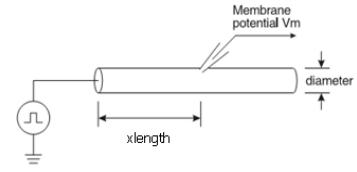

Open the Matlab m-file “axialResistance.m”. In this simulation, we will investigate how the membrane potential changes along the length of a semi-infinite cable, when we inject current at location x = 0. 

### a). Default Output

Run the model with the default parameters and describe how the membrane potential responds to a current step input delivered at t = 10 sec.

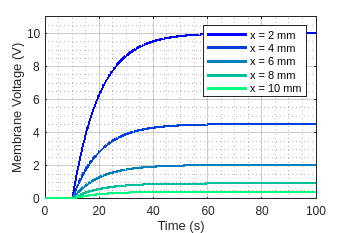

% Default parameters
p = struct('rho', 10, 'a', 1, 'Rm', 10, 'Imag', 1, 'x', 2:2:10);

% Run simulation
[time, V, lambda] = axialResistance('rho', p.rho, 'a', p.a, 'Rm', p.Rm, 'Imag', p.Imag, 'x', p.x);

% Plot results
plot_ar(time, V, p.x)

- As seen in the figure above, the membrane potential starts at zero for all distances, $x$ along the cable. When current is injected at $t=10~sec$at $x = 0$, the membrane potential rises exponentially towards a steady state value.

- This change in potential propagates along the cable. The farther a point is from $x = 0$, the lower its steady state membrane potential will be, and the longer it takes to reach steady state.

### b). Steady State vs Distance

Plot the steady state voltage for each location in 2a. What is the theoretical relationship (equation) between x and the steady state voltage? Add the theoretical relationship to your plot.

- The theoretical relationship between x and the stead state voltage is given by:


$$V(x) = V_0 \cdot e^{-\frac{x}{\lambda}}$$


% Determine steady state voltages
V_SS = V(:, end);

% Show values
T = array2table([[0 p.x]' V_SS], 'VariableNames', {'x (mm)', 'Vss (V)'});
disp(T)

    x (mm)    Vss (V)
    ______    _______

       0       9.9988
       2       4.5023
       4       2.0273
       6      0.91284
       8      0.41104
      10      0.18508



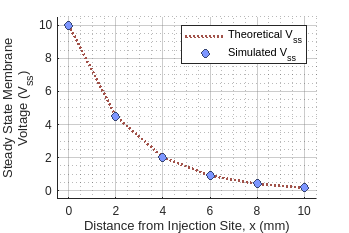

% Compute theoretical relationship between x and V
V_th = V_SS(1) .* exp(-[0 p.x]' / lambda);

% Plot results
figure('Color', 'w', 'Position', [100, 100, 450, 300]); hold on;
plot([0 p.x]', V_th, ':', 'Color', [.63 .32 .29], 'LineWidth', 2)
plot([0 p.x]', V_SS, 'o', 'Color', [.21 .27 .45], 'MarkerFaceColor', [.49 .59 1.0])
grid on;
set(gca, 'GridAlpha', 0.4, 'MinorGridAlpha', 0.3, 'GridColor', [0.5 0.5 0.5]);
grid minor;
xlabel('Distance from Injection Site, x (mm)'); ylabel(["Steady State Membrane" "Voltage (V_{ss})"]);
legend({'Theoretical V_{ss}', 'Simulated V_{ss}'})
xlim([-0.5 10.5]); ylim([-0.5 10.5]);

- The plot shows the steady state voltages at various points away from the injection site (blue circles). The red line shows the theoretical relationship between steady state membrane voltage and the distance from the injection site.

- We see that the simulated data matches the theoretical voltage values.

### c). Length Constant

Change the locations at which the voltage is being recorded by changing the “x” parameter (NOTE: keep the leading 0 in the x = [0 … ] expression). At what distance from the current input is the steady state voltage reduced to 1/e of its original value (e.g. the length constant ‘lambda’)? How does this compare to the theoretical value of the length constant?

- The length constant is defined as $\lambda = \sqrt{\frac{r_m}{r_a}}$ ; it represents the distance at which steady-state voltage is reduced to $\frac{1}{e}$ of the original value at $x=0$, i.e. $V_0$

% Print theoretical value
fprintf('Theoretical length constant, λ_T = %.2f mm', lambda)

Theoretical length constant, λ_T = 2.51 mm

% Run simulation with different x values; get SS values
X = 0:0.01:10;
[time, V, ~] = axialResistance('rho', p.rho, 'a', p.a, 'Rm', p.Rm, 'Imag', p.Imag, 'x', X);
V_SS = V(:, end);

% Simulated length constant
V_e = V_SS(1) / exp(1);
[~, min_i] = min(abs(V_SS - V_e));
X_e = X(min_i);
fprintf('Simulated length constant, λ_S = %.2f mm', X_e)

Simulated length constant, λ_S = 2.52 mm

- The steady state voltage is reduced to 1/e ($3.678\%$ of $V_0$) at $x=2.52~mm$ which matches the theoretical length constant.

### d). Voltage at Fraction of Length Constant

What is the steady state membrane potential at a distance of one-fifth the length constant?

- Evaluate $V(x) = V_0 \cdot e^{-\frac{x}{\lambda}}$ with $x=\frac{1}{5}\cdot\lambda$

% Compute steady state membrane potential
x = lambda / 5;
V_x = V_SS(1) * exp(-x/lambda);

fprintf('Steady state voltage at 1/5 of λ (%.2f mm), V = %.2f V', x, V_x)

Steady state voltage at 1/5 of λ (0.50 mm), V = 8.19 V

### e). Cause of Voltage Attenuation

Explain why there is a difference in steady state membrane potential between a location close to and a location far away from the current injection site.

- Due to the axial resistance along the cable (axon), there is a significant voltage drop the further away for move from the injection site ($x = 0~mm$). 

- The steady state voltage at any point, $x
$ is decreased by a factor of $e^{-\frac{x}{\lambda}}$ compared to the voltage at $x = 0~mm$

### f). Passive Signaling

Using the results from the above steps, if this neuron used passive signaling instead of action potentials to communicate with a downstream neuron 5 mm away, what would the steady state membrane potential be at the terminal between the two neurons? Is this an effective communication strategy?

% Compute steady state membrane potential
x = 5; % mm
V_5mm = V_SS(1) * exp(-x/lambda);

fprintf('The Steady state voltage at 5mm, V = %.2f V', V_5mm)

The Steady state voltage at 5mm, V = 1.36 V

% Compute % decrease
pct_drop = (V_SS(1) - V_5mm) / V_SS(1) * 100;
fprintf('Voltage drop at 5mm: %.2f%%', pct_drop)

Voltage drop at 5mm: 86.39%

- Passive signaling would not be an effective communication strategy due to the decrease in signal intensity when the signal travels over long distances; this occurs due to the impact of axial resistance. In this case, we see that the steady state voltage drops by 86.36% as the signal travels from $x  = 0$ to $x = 5~mm$.

### g). Effects of Increasing Radius

There are a wide variety in geometries of axonal and dendritic processes amongst the various neuron morphologies, ranging from very small (< 1 µm) to very large (1 mm) diameters. With your voltage probe fixed at a distance of 1 mm from the current injection site, determine the effects of increasing the radius (variable “a”). Test many values of a, ranging from a very small radii to radii values much greater than what are naturally observed. Plot each peak (steady state) voltage measured as a function of the length constant, lambda. Describe the relationship between the steady state voltage and the length constant.

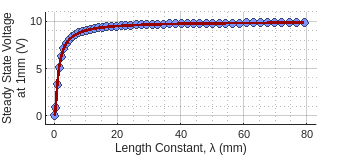

clear;

% Default parameters
p = struct('rho', 10, 'a', 1, 'Rm', 10, 'Imag', 1, 'C', 1);

% Define range of radii
radii = linspace(0.1, 10, 50);

% Preallocate results
V_1mm = zeros(size(radii, 2), 1);
lambda = zeros(size(radii, 2), 1);

% Run simulation
for i = 1:numel(radii)
    % Compute geometric properties
    a = radii(i);
    area = pi * a^2;
    ra = p.rho / area;
    R_M = 4 * pi * a^2 * p.Rm;
    rm = R_M / (2 * pi * a);
    lambda_ = sqrt(rm / ra);

    % Initialize simulation
    time  = 0:0.1:100;
    volt = zeros(numel(time), 1);

    % Run simulation (only at t=100)
    V_0 =  p.Rm * (1 - exp(-time(end) / (p.Rm * p.C))) * p.Imag;

    % Store results
    lambda(i) = lambda_;
    V_1mm(i) = V_0 * exp(-1 / lambda_);
end

% Plot results
figure('Color', 'w', 'Position', [100, 100, 450, 200]); hold on;
plot(lambda, V_1mm, 'o', 'Color', [.21 .27 .45], 'MarkerFaceColor', [.49 .59 1.0])
plot(lambda, V_1mm, '-', 'Color', [.6 0 0], 'LineWidth',2)
grid on;
set(gca, 'GridAlpha', 0.4, 'MinorGridAlpha', 0.3, 'GridColor', [0.5 0.5 0.5]);
grid minor;
xlabel('Length Constant, λ (mm)'); ylabel(["Steady State Voltage", "at 1mm (V)"]);
xlim([-3 83]); ylim([-1 11]);

- As shown in the figure, as the length constant increases, there is a corresponding increase in the steady-state voltage when measured 1mm from the current injection site. This relationship appears exponential and reaches a plateau of about 10V.

- As the radius of the neuron's processes increases, $R_m$ increases and $R_a$ decreases, resulting in increased $\lambda$ values.

- This means that neurons with larger length constants (which corresponds to larger radii), will experience less of a voltage drop off at distances far away from the injection site.

## 3). Appendix (Function Definitions)

This section contains definitions for the functions used in this notebook.

### `rc` - Simulate Parallel RC Circuit

function [time, Istep, V] = rc(varargin)
    %% Input parsing
    % -- R: Resistance (MΩ)
    % -- C: Capacitance (µF)
    % -- I: Current (nA)

    % Defaults
    params = struct('R' , 10, ... % MΩ
                    'C', 1, ... % uF
                    'I', 1); % nA

    % Parse Name, Value pairs.
    if nargin > 0
        if rem(nargin,2) ~= 0
            error('Parameters should be in ''Name'', Value pairs');
        end
        for i = 1:2:nargin
            if isfield(params, varargin{i})
                params.(varargin{i}) = varargin{i+1};
            else
                error('Unknown parameter: %s', varargin{i});
            end
        end
    end

    % Extract values & convert
    R = params.R * 10^6; %  MΩ -> Ω
    C = params.C * 10^-6; % uF -> F
    Imag = params.I * 10^-9; % nA -> A

    %% Simulation
    % time of simulation
    tstart = 0;
    tstop = 1000;
    dt = 0.01;
    time = tstart:dt:tstop; %in seconds
    % Define the stimulus:
    Istep = [zeros(1,find(time==10)) Imag.*ones(1,length(time)-find(time==10))];
    
    % Initialize voltage
    V_init = 0;
    V = [V_init zeros(1,length(time)-1)];

    % Run sim
    inc=1;
    for i = 2:length(time)
        if time(i)<10
            I = 0;
        else
            I = Imag;inc=inc+1;
        end
        V(i) = R*(1 - exp(-time(inc)/(R*C)))*I;
    end
    
    % convert from A to nA
    Istep = Istep ./ 1E-9;

    % Convert from V to mV
    V = V .* 1000;
end

### `axialResistance` - Simulate an Axon with Cable Theory

function [time, V, lambda] = axialResistance(varargin)
    %% Input parsing
    % -- rho:  Resistivity (ohm-mm)
    % -- a:    Radius of neural process (mm)
    % -- Rm:   Membrane resistance (ohms)
    % -- Imag: Stimulus current (A)
    % -- x:    Locations to record voltage (mm)

    % NOTE, when modifying X, always include x = 0 as the calculation
    % below at different distances is based on the voltage at x = 0!

    % Defaults
    params = struct('rho', 10, ...  % ohm-mm
                    'a', 1, ...     % mm
                    'Rm', 10, ...   % ohm
                    'Imag', 1, ...  % A
                    'x', 2:2:10);   % mm

    % Parse Name, Value pairs.
    if nargin > 0
        if rem(nargin,2) ~= 0
            error('Parameters should be in ''Name'', Value pairs');
        end
        for i = 1:2:nargin
            if isfield(params, varargin{i})
                params.(varargin{i}) = varargin{i+1};
            else
                error('Unknown parameter: %s', varargin{i});
            end
        end
    end

    % Unpack values
    rho = params.rho;   % resistivity in ohm-mm
    a = params.a;       % radius of the neural process (in mm)
    Rm = params.Rm;     % membrane resistance (ohms)
    Imag = params.Imag; % current injected in Amps
    x = [0 params.x];   % default is to record every 2 mm for 10mm    

    %% Simulation
    area = pi*(a)^2;    % Cross-sectional area of process (mm^2)
    ra = rho/area;      % axial resistance ohms/mm
    
    R_M = (4*pi*a^2)*Rm;  % specific membrane resistance (ohms mm^2)
    rm = R_M/(2*pi*a); % resistance of a unit lenght of membrane (ohms mm)
    
    lambda = sqrt(rm/ra);
    
    % Define the stimulus
    C = 1;    % membrane capacitance in Farads
     
    % Time of simulation
    tstart = 0;
    tstop = 100;
    dt = 0.1;
    time = tstart:dt:tstop;
    
    % Initialize voltage
    V = zeros(length(x),1);
    
    inc=1;
    for i = 2:length(time)
        if time(i)<10
            I = 0;
        else
            I = Imag; inc = inc+1;
        end
        V(1,i) = Rm*(1 - exp(-time(inc)/(Rm*C)))*I;
        for j = 1:length(x)
            V(j,i) = V(1,i)*exp(-x(j)/lambda);
        end
    end
end

### `utils` - Utility Functions

function [t_SS, V_SS] = find_SS(time, V, Istim, R)
    if size(V, 1) == 1
        V_SS = R * Istim;
        t_SS = time(find(V > .99 * V_SS, 1));
    else
        V_SS = (R .* Istim)';
        t_SS = time(arrayfun(@(i) find(V(i,:) > .99 * V_SS(i), 1), 1:2))';
    end

    % Current applied @ 10s
    t_SS = t_SS - 10;
end

function print_rc(V_SS, t_SS, labels)
    % Check if labels are provided
    if size(V_SS, 1) == 2 && nargin <3
        error('Please provide labels for the 2 lines when V is a 2xN matrix.')
    end

    % t_SS and V_SS must have the same size
    if size(V_SS) ~= size(t_SS)
        errpr('V_SS and t_SS must have equal numbers of rows')
    end

    % Print results
    if size(V_SS, 1) == 2
        for i = 1:2
            fprintf([labels{i} ':\n'])
            fstr = ['The steady state voltage, V_SS = %.2f mV.\n', ...
                    'It took %.2f seconds from current injection for the voltage to reach steady state.\n\n'];
            fprintf(fstr, V_SS(i), t_SS(i))
        end
    else
        fstr = ['The steady state voltage, V_SS = %.2f mV.\n', ...
                'It took %.2f seconds from current injection for the voltage to reach steady state.'];
        fprintf(fstr, V_SS, t_SS)
    end
end

function plot_rc(time, Istep, V, t_SS, labels)

    % Check if labels are provided for a 2xN V matrix
    if size(V, 1) == 2 && nargin < 5
        error('Please provide labels for the 2 lines when V is a 2xN matrix.');
    end

    % Shift t_SS by 10
    t_SS = t_SS + 10;

    % Create 2x1 subplot grid
    figure('Color', 'w', 'Position', [100, 100, 450, 400]);

    % Top plot: time vs Istep
    ax1 = subplot(211);
    plot(time, Istep, 'Color', [0, 0, 0.7], 'LineWidth', 2);
    ylabel('Input Current (nA)');
    set(gca, 'Color', 'white');
    grid on;
    grid minor;
    set(gca, 'GridColor', [0.7, 0.7, 0.7], 'GridAlpha', 0.4);
    set(gca, 'MinorGridColor', [0.7, 0.7, 0.7], 'MinorGridAlpha', 0.3);
    axis tight;
    ylim([min(Istep) max(Istep)*1.10]); 

    % Steady state annotation
    yrange = ylim; 
    if size(V, 1) == 1
        line([t_SS t_SS], yrange, 'Color', 'k', 'LineStyle', '--', 'HandleVisibility', 'off');
    else
        line([t_SS(1) t_SS(1)], yrange, 'Color', [0.7, 0, 0], 'LineStyle', '--', 'HandleVisibility', 'off');
        line([t_SS(2) t_SS(2)], yrange, 'Color', [1, 0.5, 0], 'LineStyle', '--', 'HandleVisibility', 'off');
    end

    % Bottom plot: time vs V
    ax2 = subplot(212);
    if size(V, 1) == 1
        plot(time, V, 'Color', [0.7, 0, 0], 'LineWidth', 2);
    else
        plot(time, V(1, :), 'Color', [0.7, 0, 0], 'LineWidth', 2, 'DisplayName', labels{1});
        hold on;
        plot(time, V(2, :), 'Color', [1, 0.5, 0], 'LineWidth', 2, 'DisplayName', labels{2});
        legend('Location', 'best');
    end
    xlabel('Time (sec)');
    ylabel('Voltage (mV)');
    set(gca, 'Color', 'white');
    grid on;
    grid minor;
    set(gca, 'GridColor', [0.7, 0.7, 0.7], 'GridAlpha', 0.4);
    set(gca, 'MinorGridColor', [0.7, 0.7, 0.7], 'MinorGridAlpha', 0.3);
    axis tight;
    ylim([min(min(V)) max(max(V))*1.10]);

    % Link axes, set limits
    linkaxes([ax1 ax2], 'x')
    xlim([0 100])

    % Steady state line and annotation
    yrange = ylim; 
    if size(V, 1) == 1
        line([t_SS t_SS], yrange, 'Color', 'k', 'LineStyle', '--', 'HandleVisibility', 'off');
    else
        line([t_SS(1) t_SS(1)], yrange, 'Color', [0.7, 0, 0], 'LineStyle', '--', 'HandleVisibility', 'off');
        line([t_SS(2) t_SS(2)], yrange, 'Color', [1, 0.5, 0], 'LineStyle', '--', 'HandleVisibility', 'off');
    end
end

function plot_ar(time, V, x)
    % Create a figure with a white background
    figure('Color', 'w', 'Position', [100, 100, 450, 300]);
    
    % Create color palette
    cmap = colormap(winter(length(x)));
    
    % Plot the data with colors from the RdOr palette
    for j = 1:length(x)
        plot(time, V(j, :), 'Color', cmap(j, :), 'LineWidth', 2);
        hold on;
    end
    
    % Show major and minor grids in gray with alpha 0.4 and 0.3
    grid on;
    set(gca, 'GridAlpha', 0.4, 'MinorGridAlpha', 0.3, 'GridColor', [0.5 0.5 0.5]);
    grid minor;
    
    % Set axis labels
    xlabel('Time (s)');
    ylabel('Membrane Voltage (V)');
    
    % Add legend
    lgd = arrayfun(@(x) "x = " + string(x) + " mm", x, 'UniformOutput', false);
    legend(lgd')
    % legend(string(x'), 'Location', 'best');

    % Y limits
    ylim([min(V(1, :)) max(V(1, :))*1.10]); 
end